# Racing Line Optimizer

### Import track data

track = readmatrix("Silverstone.csv")

track = 1.0e+03 *

    0.0034   -0.0005    0.0066    0.0065
    0.0064    0.0036    0.0066    0.0065
    0.0093    0.0076    0.0066    0.0065
    0.0122    0.0117    0.0066    0.0065
    0.0152    0.0157    0.0066    0.0065
    0.0181    0.0198    0.0066    0.0065
    0.0210    0.0238    0.0066    0.0065
    0.0240    0.0279    0.0066    0.0065
    0.0269    0.0319    0.0066    0.0065
    0.0298    0.0360    0.0066    0.0065


### Define variables

trackName = 'Silverstone';
m = 750; % Mass of vehicle
ftmax = 16; % Max acceleration (m/s^2)
fbmax = 18; % Min acceleration (m/s^2)
fnmax = 30; % Max cornering acceleration (m/s^2)

### Generate optimized path

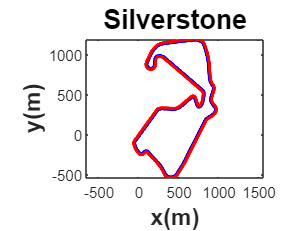


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


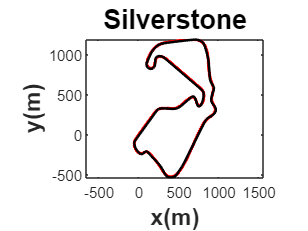

[trajMCP, trackData] = minCurvaturePathGenFunction(track,trackName);

% Click on the drop down menu to select the method for generating the optimized path

### Generate velocity profile

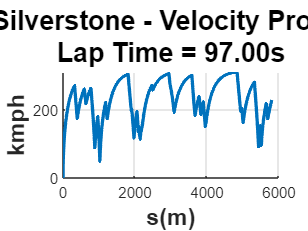

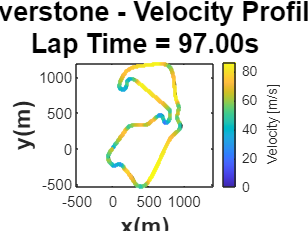

[velProf,len] = velProfCalcFunction(trajMCP,trackName,m,ftmax,fbmax,fnmax,trackData);

### References:

- The Silverstone racetrack data has been ta    ken from the following GitHub repository: [https://github.com/TUMFTM/racetrack-database](https://github.com/TUMFTM/racetrack-database) 

- The function, "velProfCalcFunction" uses the function, "curvature" that has been taken from the following File Exchange: [https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space](https://www.mathworks.com/matlabcentral/fileexchange/69452-curvature-of-a-1d-curve-in-a-2d-or-3d-space) 